close all; clc; clearvars;

TrainingFeatures_norm = readmatrix("TrainingFeatures_norm_gray.csv")';
TrainingFeatures_glau = readmatrix("TrainingFeatures_glau_gray.csv")';

data = [TrainingFeatures_norm; TrainingFeatures_glau];
labels = [zeros(size(TrainingFeatures_norm, 1), 1); ones(size(TrainingFeatures_glau, 1), 1)];

trainRatio = 0.8; % 80% for training, 20% for testing

% Create a random partition of the data
partition = cvpartition(size(data, 1), 'HoldOut', 1 - trainRatio);

% Split the data and labels into training and testing sets
X_train = data(partition.training, :);
Y_train = labels(partition.training);
X_test = data(partition.test, :);
Y_test = labels(partition.test);

rng(123); %reproductibility

% k-fold cross-validation
k = 5;
cv = cvpartition(size(X_train, 1), 'KFold', k); % Replace 'k' with the desired number of folds


classificationNeuralNetwork = fitcnet(X_train, Y_train, ...
    'LayerSizes', 10, ...
    'Activations', 'relu', 'Lambda', 0, 'IterationLimit', 1000, ...
    'Standardize', true, 'ClassNames', [false; true]);

% mdl_loss = kfoldLoss(classificationNeuralNetwork)
% Y_pred = kfoldPredict(classificationNeuralNetwork);
% accuracy = sum(strcmp(Y_pred, Y_train)) / height(X_train)


[Y_pred, scores] = predict(classificationNeuralNetwork, X_test);

acc_test = sum(strcmp(Y_pred, Y_test)) / length(Y_test)

acc_test = 0

[~, ~, ~, auc_test] = perfcurve(Y_test, scores(:,1), 1)

auc_test = 0.2716

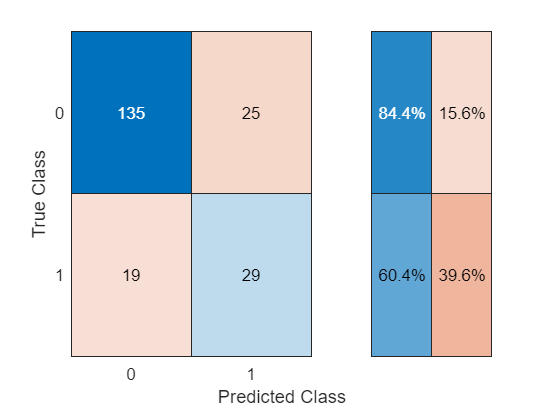


figure
confusionchart(Y_test, Y_pred, 'RowSummary','row-normalized');